## Plotting Taylor Series

- This livescript shows you how you can use MATLAB to plot a Taylor series of $\cos(x)$.

A Taylor series of any function can be written concisely as


$$f(x)=\sum_{k=0}^{\infty}\frac{f^{(k)}(x_0)}{k!}(x-x_0)^k$$


It is sometimes useful to expand this summation to clearly see all the terms of the Taylor series


$$f(x) =f(x_0)+f'(x_0)(x-x_0)+\frac{f''(x_0)}{2!}(x-x_0)^2+\frac{f'''(x_0)}{3!}(x-x_0)^3+\frac{f^{iv}(x_0)}{4!}(x-x_0)^4 +....$$


Finding the Taylor series of a function now just involve finding all the terms on the right hand side of the equation above.  For this example, we will find the Taylor series of $f(x)=\cos(x)$ "about $x=0$" so we set $x_0=0$.


$$f(x_0)=f(0)=\cos(0)=1$$



$$f'(x_0)=f'(0)=\left.\frac{df}{dx}\right|_{x=0}=-\sin(0)=0$$



$$f''(x_0)=f''(0)=\left.\frac{d^2f}{dx^2}\right|_{x=0}=-\cos(0)=-1$$



$$f'''(x_0)=f'''(0)=\left.\frac{d^3f}{dx^3}\right|_{x=0}=\sin(0)=0$$



$$f^{iv}(x_0)=f^{iv}(0)=\left.\frac{d^4f}{dx^4}\right|_{x=0}=\cos(0)=1$$



$$\vdots$$


Substituting into the Taylor series will give you


$$f_{taylor}(x)=1-\frac{1}{2}x^2+\frac{1}{24}x^4-\frac{1}{720}x^6+.....$$


We will now plot the Taylor series for $f\left(x\right)=\mathrm{cos}\left(x\right)\;$for $-5\leq x\leq 5$.

Define a vector from $-5\leq x \leq 5$.

x=-5:0.1:5

x =    -5.0000   -4.9000   -4.8000   -4.7000   -4.6000   -4.5000   -4.4000   -4.3000   -4.2000   -4.1000   -4.0000   -3.9000   -3.8000   -3.7000   -3.6000   -3.5000   -3.4000   -3.3000   -3.2000   -3.1000   -3.0000   -2.9000   -2.8000   -2.7000   -2.6000   -2.5000   -2.4000   -2.3000   -2.2000   -2.1000   -2.0000   -1.9000   -1.8000   -1.7000   -1.6000   -1.5000   -1.4000   -1.3000   -1.2000   -1.1000   -1.0000   -0.9000   -0.8000   -0.7000   -0.6000   -0.5000   -0.4000   -0.3000   -0.2000   -0.1000


Define the true function, $f_{real}(x)=\cos(x)$

freal=cos(x)

freal =     0.2837    0.1865    0.0875   -0.0124   -0.1122   -0.2108   -0.3073   -0.4008   -0.4903   -0.5748   -0.6536   -0.7259   -0.7910   -0.8481   -0.8968   -0.9365   -0.9668   -0.9875   -0.9983   -0.9991   -0.9900   -0.9710   -0.9422   -0.9041   -0.8569   -0.8011   -0.7374   -0.6663   -0.5885   -0.5048   -0.4161   -0.3233   -0.2272   -0.1288   -0.0292    0.0707    0.1700    0.2675    0.3624    0.4536    0.5403    0.6216    0.6967    0.7648    0.8253    0.8776    0.9211    0.9553    0.9801    0.9950


Define the Taylor series of $\cos(x)$, $f_{taylor}(x)=1-\frac{1}{2}x^2+\frac{1}{24}x^4-\frac{1}{720}x^6+.....$

ftaylor=ones(size(x))

ftaylor =   -11.5000  -11.0050  -10.5200  -10.0450   -9.5800   -9.1250   -8.6800   -8.2450   -7.8200   -7.4050   -7.0000   -6.6050   -6.2200   -5.8450   -5.4800   -5.1250   -4.7800   -4.4450   -4.1200   -3.8050   -3.5000   -3.2050   -2.9200   -2.6450   -2.3800   -2.1250   -1.8800   -1.6450   -1.4200   -1.2050   -1.0000   -0.8050   -0.6200   -0.4450   -0.2800   -0.1250    0.0200    0.1550    0.2800    0.3950    0.5000    0.5950    0.6800    0.7550    0.8200    0.8750    0.9200    0.9550    0.9800    0.9950


%ftaylor=ones(size(x))-(1./2.)*x.^2
%ftaylor=ones(size(x))-(1./2.)*x.^2+(1./24.)*x.^4
%ftaylor=ones(size(x))-(1./2.)*x.^2+(1./24.)*x.^4-(1./720.)*x.^6

Now plot $f_{real}(x) $ and $f_{taylor}(x)$

plot(x,freal,'k-',x,ftaylor,'b-o')
xlabel('x')
ylabel('f(x)')

Now limit the function in the y axis so that it is clearer to see what is going on 

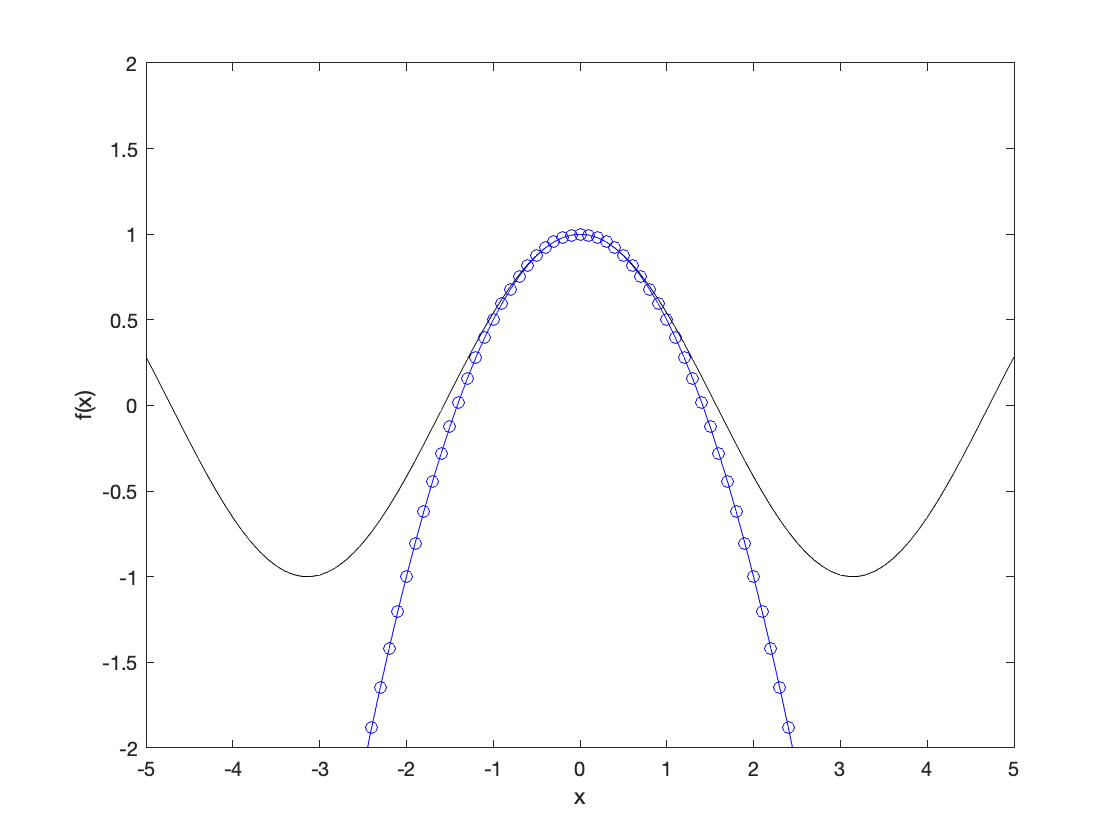

ylim([-2,2])
xlim([-5,5])

Note that the Taylor series approximates the value of $$f_{real}$(x)$ very well at $x\approx 0$.  For $x\neq 0$, the approximation gets better and better if you add more and more terms to $f_{taylor}(x)$.